clear all
clear

## initial postion of guide and scout

% create initial positon of guide, scout and  obstacles
L = 64;  % dimension of map
initPos =randi([1,L],3,2);
sGuide0 = [initPos(1,1) initPos(1,2)]; %  init guide location from random distribution
sScout0 =[initPos(2,1) initPos(2,2)];%  init scout location from random distribution
obstacleLoca = [ num2str(initPos(3,1))  num2str(initPos(3,2)) ]

obstacleLoca = '918'

s0 = [sGuide0;sScout0];
% create Map
gridMap = createGridWorld(L,L,'Kings') 

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


gridMap.TerminalStates = ['[' num2str(sGuide0(1,1)) ',' num2str(sGuide0(1,2)) ']' ]

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: [0×1 string]
    TerminalStates: "[9,8]"


gridMap.ObstacleStates = ['[' num2str(initPos(3,1)) ',' num2str(initPos(3,2)) ']' ]

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: "[9,18]"
    TerminalStates: "[9,8]"


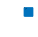

env = rlMDPEnv(gridMap);
% env.UseFastRestart  = 'true';
% Reset Function 
env.ResetFcn = @(in) resetFcn(in,obstacleLoca);

plot(env)

%gridMap.Actions = 'Kings'
% sGuide0 = [ ];
% 
% 
% sScout0 = [ ];
% R = 100 * 10^3; %replay buffer
% epsilon0 = 0.9; % initial epsilon 
% epsilon_end = 0.05;
% lamda = 1000; % decay rate of epsilon
tau = 0.005;
gamma = 0.99;
% epsilon_t = epsilon_end + (epsilon0 -epsilon_end ).*exp(-(epsilon )./lamda); % epsilon-greedy exploration
episode = 1; % initial training episodes
episodeMax = 5e5;% max training episodes


##  Max sample time and simulation time,Max Number of step s

Ts = 0.1;
Tf = 100;
maxsteps = ceil(Tf/Ts);

## Action space and Obs space

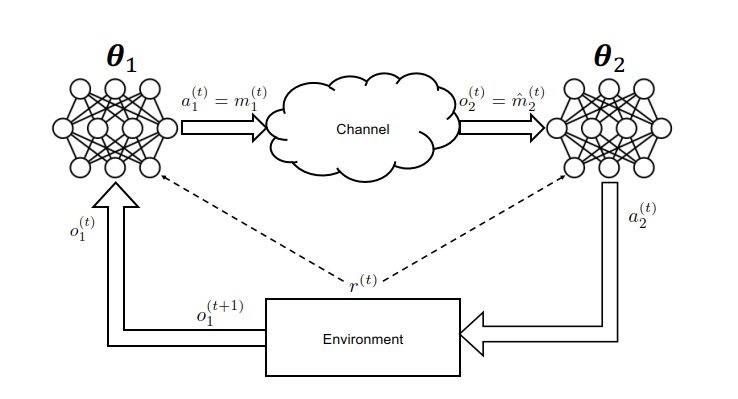

observation 1 and action 1 (Guide)

obsSize = [L L 3];
obsInfo = rlFiniteSetSpec(obsSize);
obsInfo.Name = "Observation";
obsInfo.Description = "guide x location, guide y location,  scout x location, scout y locaton";
% trasition probability 
% numAct = 16;
% % actionSpace = {[1,0] ,[-1,0] ,[0,1] ,[0,-1] ,[1,1] ,[-1,1] ...
% %     ,[-1,-1] ,[1,-1],[2,0] ,[-2,0] ,[0,2] ,[0,-2] ,[2,2] ...
% %     ,[-2,2] ,[-2,-2] ,[2,-2]};
% actionSpace = {0,1,2,3,4,5,6,7,8,9,10,11,12,1};
% actInfo = rlFiniteSetSpec(actionSpace);
% actSize = [7 1];
% actInfo.Name ="Act1";
% actInfo.Description = "Action 1 = Message sent to Scout ";
% actInfo = rlFiniteSetSpec(actSize);
actInfo = getActionInfo(env);

theta = 0.65 %  probability of random neighboring cell 

theta = 0.6500

z =  {[1, 0], [1, 1], [0, 1], [-1, 1], [-1, 0], [0, -1],...
    [-1, -1], [1, -1]}; % random distributed term
cell2mat(z(randi([1 8],1,1)))+cell2mat(z(randi([1 8],1,1)));
lenz =length(z)

lenz = 8

% for i = 1: episodeMax
% if  binornd(1,epsilon) == 1; 
%  s(i+1) = s(i)+a(i);
% else
% 
% s(i+1) = s(i)+a(i)+z(unidrnd(lengz)); 
% end


#### reward  function

% if sGuidet == sScoutt
%     rt = 10;
% else
%     rt = -1;
% end
%  r = entropy() % negative cross-entropy (CE) loss function


## Build Agent for Guide

rng(0)

## Guide 

%  actorNetWork1 = [imageInputLayer(obsInfo,'Normalization' ,'none' ,'Name' ,'observations')   ...
%  fullyConnectedLayer(64,"Name","Linear1")  reluLayer("Name","Relu1") ...
%  fullyConnectedLayer(64,"Name","Linear2") reluLayer("Name","Relu2")]
%  actorNetWork1 = dlnetwork(actorNetWork1);
%  rlContinuousDeterministicActor();
%  analyzeNetwork(actorNetwork1)
% 
%  criticNetwork1 = [imageInputLayer(obsInfo,'Normalization','none' ,'Name' ,'observations')  ... 
%      fullyConnectedLayer(64,"Name","Linear1") ...
%      reluLayer("Name","Relu1") fullyConnectedLayer(64,"Name","Linear2") reluLayer("Name","Relu2")]
% criticOpts = rlOptimizerOptions('LearnRate',0.02,'GradientThreshold',1); % critic optimisation option
% criticNetwork1 = dlnetwork(criticNetwork1);
%  analyzeNetwork(criticNetwork1)
%  rlQValueFunction();
RLAgentType = inputdlg("Guide/ Agent 1 Reinforcement Learning Type (DQN/DDPG/RL/ACAgent): ", "Choices",[1 50])


RLAgentType =

  0×0 empty cell array



RLAgentType = cell2mat(RLAgentType);
  switch RLAgentType

  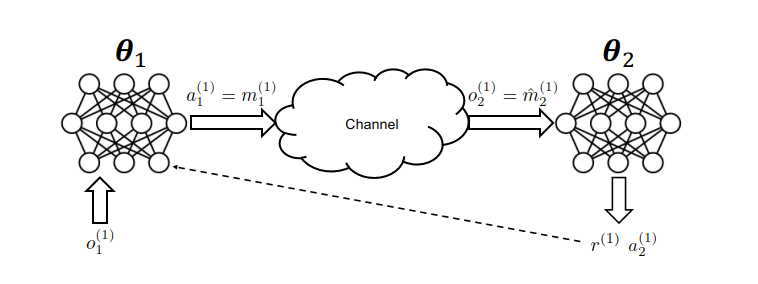

Create DQN Agent

case 'DQN'
% create Depp Neural Network  &&& Define Paths
dnn = [
    featureInputLayer(4,'Normalization','none','Name','state')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64, 'Name','CriticStateFC2')
    reluLayer('Name','CriticRelu2')
     fullyConnectedLayer(64, 'Name','CriticStateFC3')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(4,'Name','output')];


     dnn =dlnetwork(dnn);
% Specify options for the critic optimizer
criticOptions = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'L2RegularizationFactor',1e-4);
% Create the critic representation using the specified deep neural network
% and options
critic1 = rlVectorQValueFunction(dnn,obsInfo,actInfo);
% DQN agent optimizer Options
DQNAgentOptOpts = rlOptimizerOptions('LearnRate',1e-3, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

% specify the DQN agent options 
agent1Opts = rlDQNAgentOptions(...
    'SampleTime',-1,... event-based
    'UseDoubleDQN',false,...
    'CriticOptimizerOptions',DQNAgentOptOpts,... ADAM Optimizer with learning rate 0.001
    'ExperienceBufferLength',1e65,...  % replay buffer 
    'MiniBatchSize',128 ... sample batch size 
     );

agent1Opts.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
agent1Opts.EpsilonGreedyExploration.Epsilon = 0.9;
agent1Opts.EpsilonGreedyExploration.EpsilonMin = 0.05;
% create rl Deep Q Network agent
  agent1 = rlDQNAgent(critic1, agent1Opts);
  rlAgentInitializationOptions
  
  crossentropy
  train


  Create DDPG

case 'DDPG'
    % create actor network 
    
 actorNetWork1 = [imageInputLayer(4,'Normalization' ,'none' ,'Name' ,'observations')   ...
 fullyConnectedLayer(64,"Name","Linear1")  reluLayer("Name","Relu1") ...
 fullyConnectedLayer(64,"Name","Linear2") reluLayer("Name","Relu2")]
 actorNetWork1 = dlnetwork(actorNetWork1);
 
 
 analyzeNetwork(actorNetwork2)
 actorOpts = rlOptimizerOptions('LearnRate',1e-04,'GradientThreshold',1);
 actor = rlContinuousDeterministicActor(actorNetwork1,obsInfo,actInfo);
 
%% create critic network
% create Observation Path
obsPath = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')];


% create Action Path
actPath =[featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','CriticActionFC1','BiasLearnRateFactor',0)];

%create Common Path
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% add  Observation Path and Action Path
criticNetwork1 = layerGraph();
criticNetwork1 = addLayers(criticNetwork1,statePath);
criticNetwork1 = addLayers(criticNetwork1,actionPath);
criticNetwork1 = addLayers(criticNetwork1,commonPath);
 
 
     
   
   
 
criticNetwork1 = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
criticNetwork1 = dlnetwork(criticNetwork1);  
  
criticOpts = rlOptimizerOptions('LearnRate',0.02,'GradientThreshold',1); % critic optimisation option
  
  
analyzeNetwork(criticNetwork2)  


 
  
 
% DDPG agent options
agent1Opts = rlDDPGAgentOptions('SampleTime',Ts,...
    'CriticOptimizerOptions',criticOpts,... %% Critic Options
    'ActorOptimizerOptions',actorOpts,... %% Actor Options
    'ExperienceBufferLength',1e6,... %% Replay Buffer 
    'DiscountFactor',0.99,...
    'MiniBatchSize',128)


  % create DDPG Agent
  agent1 = rlDDPGAgent(actor,critic,agent1Opts);

crossentropy()
train()


Create Reinforcement Agent

case 'RL'
%  create a Q table using the observation and action specifications
qTable = rlTable(obsInfo, actInfo);
qFunction = rlQValueFunction(qTable, obsInfo, actInfo);
RLAgentOptions = rlOptimizerOptions("LearnRate",1,"Algorithm","adam");



rlAgentInitializationOptions
% specify Agent options
RLAgentOpts =rlQAgentOptions("DiscountFactor",0.9,"CriticOptimizerOptions", qOptions)
RLAgentOpts.EpsilonGreedyExploration.Epsilon = 0.9;
RLAgentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.01;
% create Q Value Agent
agent1 = rlQAgent(qFunction,RLAgentOpts)
% create train options
trainOpts = rlTrainingOptions("MaxEpisodes",episodeMax)
train


 Create Actor-Critic Agent

*Gt*=*ts*+*N*∑*k*=*t*(*γk*−*tRk*)+*bγN*−*t*+1*V*(*Sts*+*N*;*ϕ*)

case 'ACAgent'

% create actor network
actorNetWork1 = [featureInputLayer(4,'Normalization','none','Name','state')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(1, 'Name', 'CriticFC')];
actorOpts = rlOptimizerOptions()   
actor = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo)


% create critic network
criticNetWork1 = [featureInputLayer(4,'Normalization','none','Name','state')
    fullyConnectedLayer(64, 'Name','ActorStateFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(2,'Name','action')]
criticOpts =rlOptimizerOptions()
critic = rlValueFunction(criticNetWork1,obsInfo)


% specify the AC agent options
rlAgentInitializationOptions   
ACAgentOpts = rlACAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'EntropyLossWeight',0.01);
% create AC agent
agent1 = rlACAgent(actor,critic,ACAgentOpts) 
train()
  end

SWITCH expression must be a scalar or a character vector.

Guide Encoder 

   act1Outcome = [1;2;3;4;5;6;7;8];
   msg1 = dec2bin(act1Outcome)
%     msg1 = act1Conv(act1Outcome)
   lenCode = 7;%codeword length
   lenMsg = 4; %message length 
   encode(msg1,lenCode,lenMsg,'hamming/binary')
    A2 = {[1 0 0 0], [0 0 0 1],[0 0 1 0],[1 0 0 0], ...
        [0 1 0 1],[1 0 1 0],[1 1 0 1], [1 1 0 0], ...
        [0 0 0 0],[0 0 1 1],[0 1 1 0],[1 0 0 1],...
        [0 1 1 1],[1 1 1 0] ,[1 1 1 1],[0 1 0 0]}; % Scout observation 2 
   

## Create Noisy Channel 

  ModeNoise = input("insert BSN, AWGNW or AWGNO: ","s")
  ModeNoise = inputdlg("insert BSN, AWGNW or AWGNO: ","Mode Noise Choices",[1 50])
  ModeNoise = cell2mat(ModeNoise);
  switch ModeNoise 


Binary Symmetric Noise

    case 'BSN'
    prob = 0.15 ;
    ndata = bsc(msg,prob) %  Binary symmetric channel
        
        m1 = [ 2 0 16 7];
    M = 4 ;
    prob = 0.75
    n = binornd(1,prob,[1 M])
    for i = 1:M 
     mdelta(i) = m1(i)+n(i);
    end
    

Additive White Gaussian Noise

snr =  1;% signal to noise ratio
 %signal power


with Binary Phase Shift Modulation 

   case 'AWGNW'
    M = 2; % binary phase 
    snr = 1;% signal to noise ratio
    modMsg = pskmod(msg,M)% modulated signal
    rng(0);
    nData = awgn(modMsg,snr)

without Binary Phase Shift Modulation ( General quadrature amplitude modulation (QAM)** Modulation over AWGN Channel)**

   case 'AWGNO'
       snr = 1;
    c = [-5 -5i 5 5i -3 -3-3i -3i 3-3i 3 3+3i 3i -3+3i -1 -1i 1 1i]; % example
    sigpower = pow2db(mean(abs(c).^2));
    M = length(c); % Create a 16-QAM constellation
    modData = genqammod(msg,c); % Modulate the data by using the genqammod function. %
    % General QAM modulation is necessary because the custom constellation is not rectangular.
    nData = awgn(modData,snr,signalpower)
    normrnd(0,theta)

    end

## Scout 

Scout Decoder

  decMsg =decode(msg,lenCode,lenMsg,'hamming/binary');
  numerr = biterr(data,decData);
% switch act1Outcome
%     case 1
%         msg = [0 0 0 0];
%     case 2
%         msg = [0 0 0 1];
%     case 3
%         msg = [0 0 1 0];
%     case 4
%         msg = [0 0 1 1];
%     case 5
%         msg = [0 1 0 0];
%     case 6
%         msg = [0 1 0 1];
%     case 7
%         msg = [0 1 1 0];
%     case 8
%         msg = [0 1 1 1];
msg2 = bin2dec(msg1);

Scout Observation 2 and action 2 (Scout)

obs2Info = rlFiniteSetSpec();



act2Info = getActionInfo(env);

DQN agent

%define Observation Information


    
    % define action information
% actionSpace = {0,1,2,3,4,5,6,7,8,9,10,11,12,1};
% actInfo = rlFiniteSetSpec(actionSpace);
% actInfo.Name ="Acts";
% actInfo.Description = "Scout can move in 8 direction with max 2 steps"    

% create Deep Neural Network
% nI = observationInfo.Dimension(1);  % number of inputs (6)
% nL = 120;                           % number of neurons
% nO = numel(actionInfo.Elements);    % number of outputs (31)

dnn = [ featureInputLayer(obsInfo2,'Normalization','none','Name','state' )...
    fullyConnectedLayer(64,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(64,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(nO,'Name','fc3')];

 dnn = dlnetwork(dnn);
 analyzeNetwork(dnn)
 % Specify options for the critic optimizer
criticOptions = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'L2RegularizationFactor',1e-4);
% Create the critic representation using the specified deep neural network
% and options
critic = rlVectorQValueFunction(dnn,obsInfo,actInfo);

% DQN agent optimizer Options
DQNAgentOptOpts = rlOptimizerOptions('LearnRate',1e-3, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

% specify the DQN agent options 
agent2Opts = rlDQNAgentOptions(...
    'SampleTime',-1,... event-based
    'UseDoubleDQN',false,...
    'CriticOptimizerOptions',DQNAgentOptOpts,... ADAM Optimizer with learning rate 0.001
    'ExperienceBufferLength',1e5,...  % replay buffer  
    'MiniBatchSize',128 ... sample batch size 
     );

agent2Opts.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
agent2Opts.EpsilonGreedyExploration.Epsilon = 0.9;
agent2Opts.EpsilonGreedyExploration.EpsilonMin = 0.05;

% create rl Deep Q Network agent
  agent2 = rlDQNAgent(actor2,critic2, agent2Options);

 

 Reset Function

%    env.ResetFcn = @(sGuide0,sScout0) randi([1,L],2,2);


Training Options [ Centralised Learning Decentralised Execution]  

  trainOpts = rlMultiAgentTrainingOptions("AgentGroups",{[1,2]}, ...
      'LearningStrategy',"centralized",...
           "MaxEpisodes",episodeMax, ...
            "MaxStepsPerEpisode",1000);

  Train the Guide and Scout Agents

  centralisedTrainResult = train([agent1,agent2],env,trainOpts);

Simulation Options

   simOpts = rlSimulationOptions( 'MaxSteps',1000, ...
       'NumSimulations',10);

Simulation

  experiment = sim(env,[agent1,agent2],simOpts)